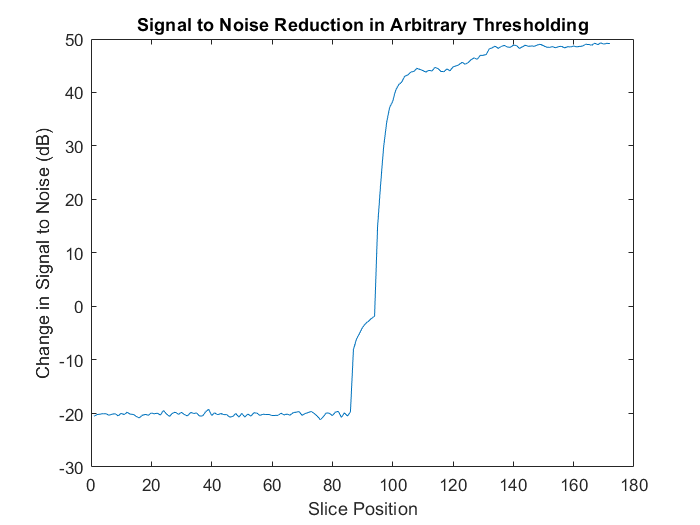

filename = 'ABIDE_MRI_data.nii';

Vol = niftiread(filename);

% Noise settings:
m = 0; %mean position for gaussian noise
v = -10; % exponential variance in noise

[Nvol, Dvol, snrN, snrD, r] = TestVolume(Vol, m, 10^v);

clf
plot(snrN - snrD)
ylabel('Change in Signal to Noise (dB)')
xlabel('Slice Position')
title('Signal to Noise Reduction in Arbitrary Thresholding')

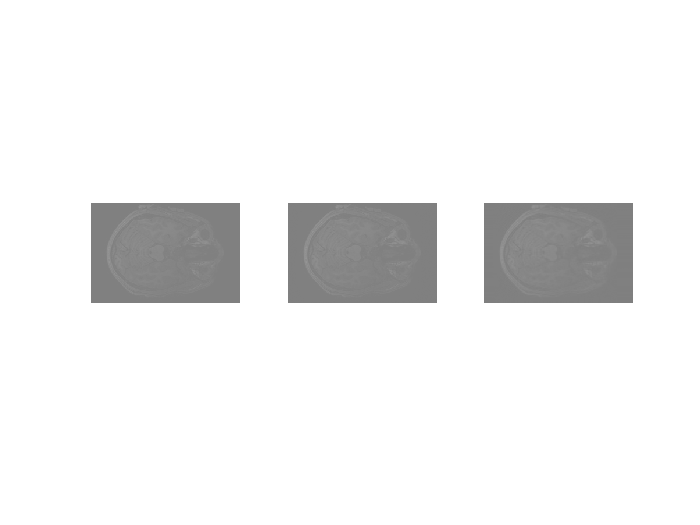


subplot(1,3,1)
imshow(Vol(:, :, 140));

subplot(1,3,2)
imshow(Nvol(:, :, 140));

subplot(1,3,3)
imshow(Dvol(:, :, 140))

%averages:

avgNoise = mean(snrN)

avgNoise = 94.0757

avgDenoise = mean(snrD)

avgDenoise = 83.6807

avgRank = mean(r)

avgRank = 21.5291